## Implementación digital del filtro:

y*(t) = b1 x*(t) + b2 x*(t-T) - a1 y*(t-T) - a2 y*(t-2T)

### Inicialización

clear
close all
import java.lang.*; %Librería para los delay

%Definición de los coeficientes
a1 = 1;
a2 = 2;
b1 = 1;
b2 = 2;

%Definición del periodo de muestreo T
T = 0.1;

%Inicialización de valores "pasados" para el primer ciclo
x_init = 0;
x_init2 = 0;
y_init = 0;
y_init2 = 0;

%Definición de arrays que representarán a los registros
x = [];
y = [];

%Se agregan los valores iniciales a los registros
x = [x x_init x_init2];
y = [y y_init y_init2];

### Ciclo para el cálculo de la salida

%Mientras no hayan pasado n iteraciones:
iter = 30;
while (iter>0)    
    x_actual = ADC();   %Se lee la entrada actual
    x_ant = x(end);      %Se lee la entrada anterior
    y_ant = y(end);      %Se lee la salida anterior
    y_ant2 = y(end-1);     %Se lee la salida tras-anterior
    
    %Se calcula la salida actual
    y_actual = b1*x_actual + b2*x_ant - a1*y_ant - a2*y_ant2;
    
    %Se guardan los valores actuales en los registros
    x = [x x_actual];
    y = [y y_actual];
    iter = iter - 1;
    
    %Se aplica el delay de T segundos
    Thread.sleep(T*1000);
end

%Mostrar los valores de los registros
fprintf('Los valores de la entrada son:');

Los valores de la entrada son:

fprintf('%g,', x);

0,0,0.598524,0.470924,0.695949,0.699888,0.638531,0.0336038,0.0688061,0.3196,0.530864,0.654446,0.407619,0.819981,0.718359,0.968649,0.531334,0.325146,0.105629,0.610959,0.778802,0.423453,0.0908233,0.266471,0.153657,0.281005,0.440085,0.527143,0.457424,0.875372,0.518052,0.943623,


fprintf('Los valores de la salida son:');

Los valores de la salida son:

fprintf('%g,', y);

0,0,0.598524,1.06945,-0.628697,0.581588,2.71411,-2.56662,-2.72559,8.31605,-1.69481,-13.2211,18.3272,9.75021,-44.0464,26.9513,63.6101,-116.125,-10.3393,243.411,-220.732,-264.11,706.511,-177.844,-1234.49,1590.77,879.218,-4059.35,2302.42,5818.06,-10420.6,-1213.5,

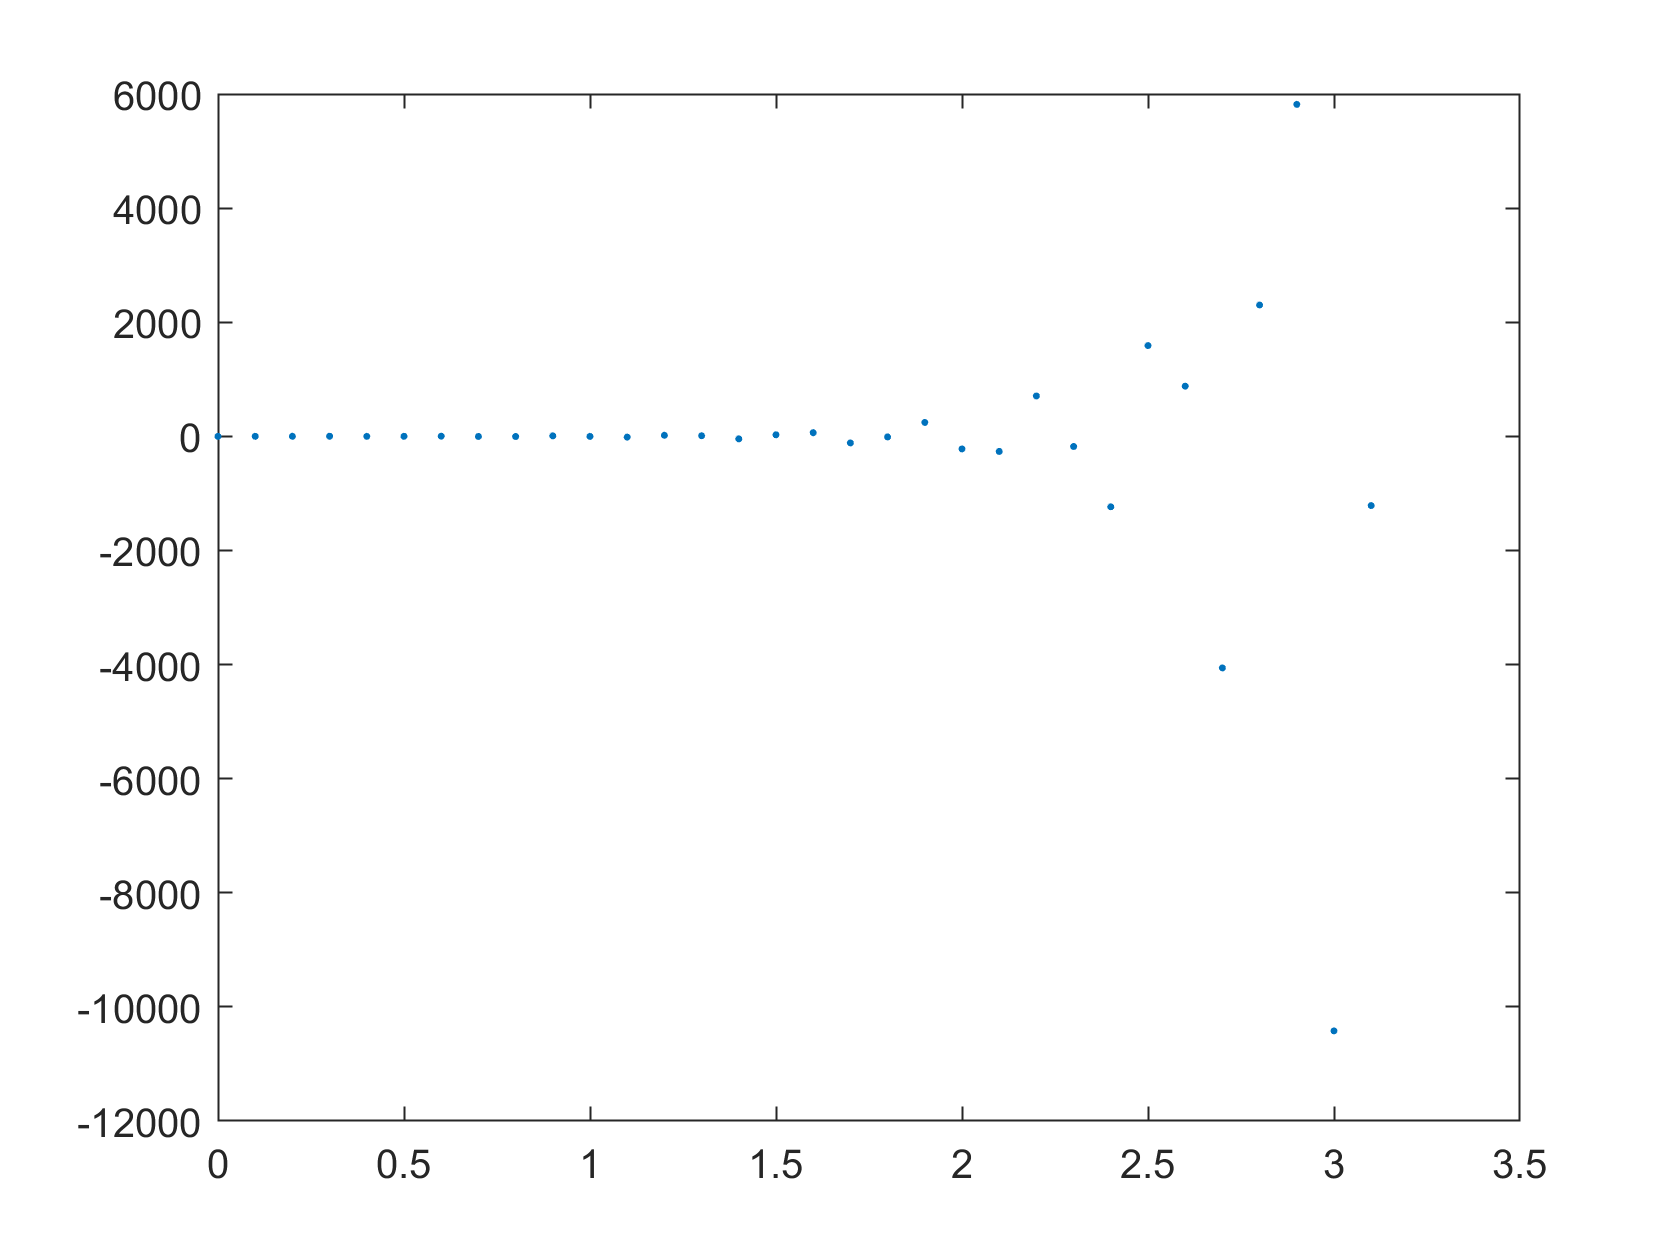


%Gráfico salida vs. tiempo
t = 0:T:T*(length(y)-1);
plot(t,y,'.')

function x = ADC()
    %Se generan número aleatorios que representan a las
    %lecturas que realizaría el ADC
    x = rand();
end